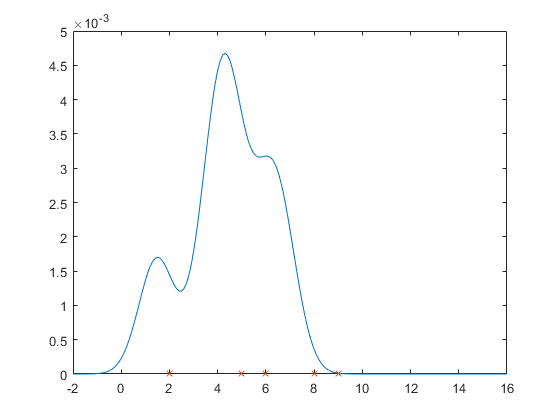

partikel = [2,5,6,6,8,9];
x = (-2:0.1:16).';
n= length(x);
nP = length(partikel);

h = (4/(3*nP))^(1/5);

func = f(x,h,partikel);
plot(x,func,partikel,zeros(nP,1),'x')

function kernel = K(x,c)
    kernel = 1/(sqrt(2)*pi) * exp(-0.5*(x-c)^2);
end

function kernelDensity =  f(x,h,p)
    n = length (x);
    nP = length(p);
    sum = zeros(n,1);
    for i = 1: n
        for j = 1 : nP
            sum(i) = sum(i) + K(x(i)/h,p(j));
        end
        
    end
    kernelDensity = sum ./(n*h);
end